alpha = 2;          
stopband_attenuation = 40; 
Fs = 720;   
Fp = 10;       
Fstop = 20;        


Wc = 2 * Fp / Fs;
Ws= 2*Fstop/Fs;

[n,Wn] = buttord(Wc,Ws,alpha,40) 

[z,p] = butter(n,Wn);
sos = tf(z,p,1/Fs);
pzmap(sos)

% Plot the pole-zero plot
figure;
pzmap(sos);
title('Pole-Zero Plot');
grid on;

% Plot the Bode plot
figure;
bode(sos);
title('Bode Plot');
grid on;


t = 0:1/Fs:1;
impulse_response = impulse(sos, t);
step_response = step(sos, t);

% Plot the impulse response and step response on the same graph
figure;
plot(t, impulse_response, 'b', 'LineWidth', 2, 'DisplayName', 'Impulse Response');
hold on;
plot(t, step_response, 'r', 'LineWidth', 2, 'DisplayName', 'Step Response');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response and Step Response');
legend('show');
grid on;

alpha = 2;        % Maximum passband ripple (in dB)
A = 40;             % Minimum stopband attenuation (in dB)
f_pass = 10;        % Passband edge frequency (in Hz)
f_stop = 20;        % Stopband edge frequency (in Hz)
fs = 720;           % Sampling frequency (in samples/sec)
ecg_data=load('ECG_Data_6.txt')
% Calculate the minimum filter order using butterord
[N, Wn] = buttord(f_pass / (fs/2), f_stop / (fs/2), alpha, A);

% Design the Butterworth filter
[b, a] = butter(N, Wn, 'low');

% Apply the Butterworth filter to the ECG data (assuming you have loaded the data)
filtered_ecg = filtfilt(b, a, ecg_data);

% Create a time vector for plotting
t = (0:length(ecg_data) - 1) / fs;

% Plot the original and filtered signals in the same figure
figure;
subplot(2, 1, 1);
plot(t, ecg_data);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2, 1, 2);
plot(t, filtered_ecg);
title('Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

% Adjust the plot layout
sgtitle('ECG Signal and Filtered Signal Comparison');

filename = 'instru2.wav';
[y, Fs] = audioread(filename);

% Compute the spectrogram of the audio signal
window_size = 1024;  % You can adjust this based on your preference
overlap = 512;       % Adjust overlap as needed
nfft = 2048;         % Adjust FFT size as needed

spectrogram(y, hamming(window_size), overlap, nfft, Fs, 'yaxis');
title('Original Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% Design a digital Butterworth bandpass filter
f_passband = [100 1000];  % Passband frequency range (adjust as needed)
order = 4;                % Filter order (adjust as needed)

[b, a] = butter(order, f_passband / (Fs/2), 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filter(b, a, y);

% Save the filtered audio to a new WAV file
output_filename = 'filtered_instruα.wav';
audiowrite(output_filename, filtered_signal, Fs);

% Plot the spectrogram of the filtered audio
figure;
spectrogram(filtered_signal, hamming(window_size), overlap, nfft, Fs, 'yaxis');
title('Filtered Spectrogram');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

% Play the filtered audio
sound(filtered_signal, Fs);

%Design the Chebyshev filter
alpha = 2;           % Maximum passband ripple in dB
stopband_attenuation = 40; % Minimum stopband attenuation in dB
Fs = 720;            % Sampling frequency in samples/sec
Fp = 10;             % Passband edge frequency in Hz
Fstop = 20;          % Stopband edge frequency in Hz

% Calculate normalized cutoff frequencies (Wc and Ws)
Wc = 2 * Fp / Fs;
Ws = 2 * Fstop / Fs;

% Determine filter order (N) using the formula for Chebyshev Type I filter
[n, Wn] = cheb1ord(Wc, Ws, alpha, stopband_attenuation);

% Design the Chebyshev Type I filter
[z, p] = cheby1(n, alpha, Wn);
sos_chebyshev = tf(z, p, 1/Fs);

% Design the Butterworth filter as in the previous example
[n_butterworth, Wn_butterworth] = buttord(Wc, Ws, alpha, stopband_attenuation);
[z_butterworth, p_butterworth] = butter(n_butterworth, Wn_butterworth);
sos_butterworth = tf(z_butterworth, p_butterworth, 1/Fs);

% Compare the filter orders
fprintf('Chebyshev Type I Filter Order: %d\n', n);

Chebyshev Type I Filter Order: 5


fprintf('Butterworth Filter Order: %d\n', n_butterworth);

Butterworth Filter Order: 8


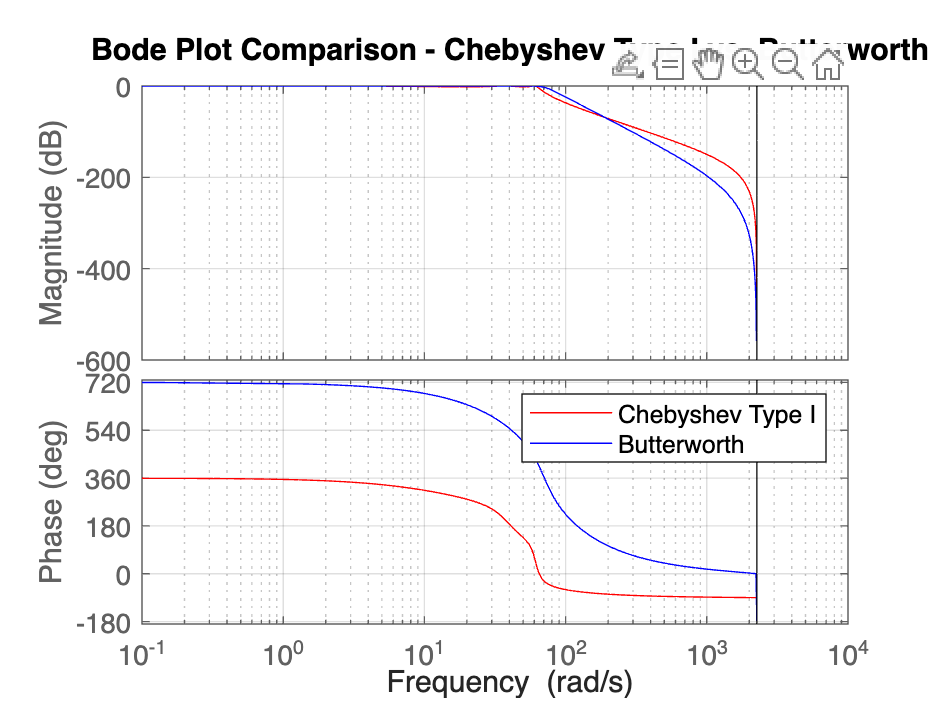


% Plot the Bode plots of Chebyshev Type I and Butterworth filters
figure;
bode(sos_chebyshev, 'r', sos_butterworth, 'b');
title('Bode Plot Comparison - Chebyshev Type I vs. Butterworth');
legend('Chebyshev Type I', 'Butterworth');
grid on;

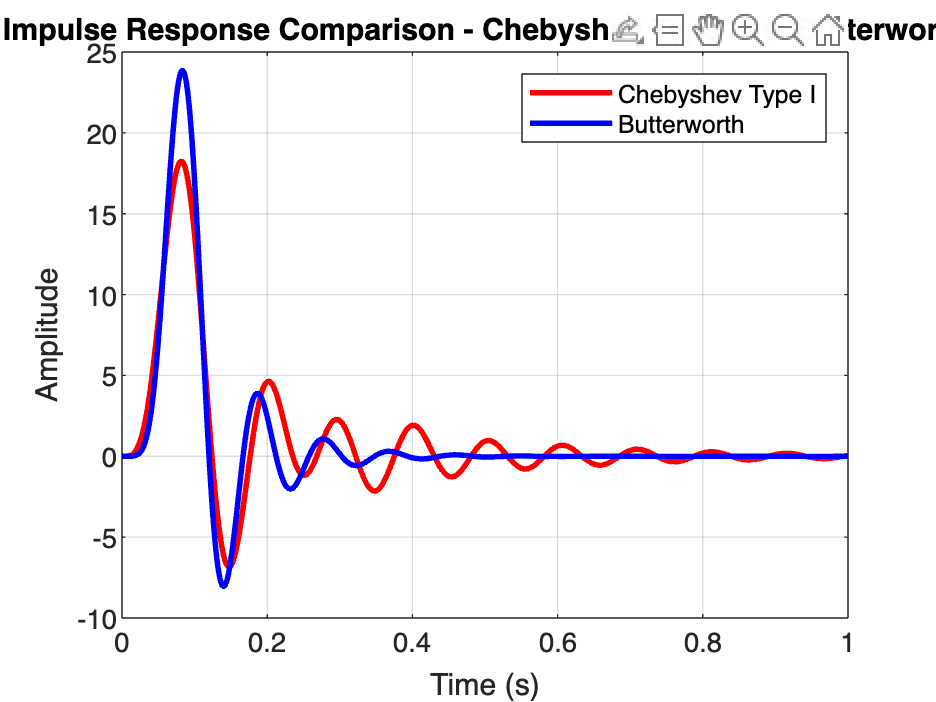


% Define the time vector for 1 second
t = 0:1/Fs:1;

% Compute the impulse response of the Chebyshev Type I filter
impulse_response_chebyshev = impulse(sos_chebyshev, t);

% Compute the step response of the Chebyshev Type I filter
step_response_chebyshev = step(sos_chebyshev, t);

% Compute the impulse response and step response of the Butterworth filter
impulse_response_butterworth = impulse(sos_butterworth, t);
step_response_butterworth = step(sos_butterworth, t);

% Plot the impulse response and step response of both filters on the same graph
figure;
plot(t, impulse_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, impulse_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'northeast');
grid on;

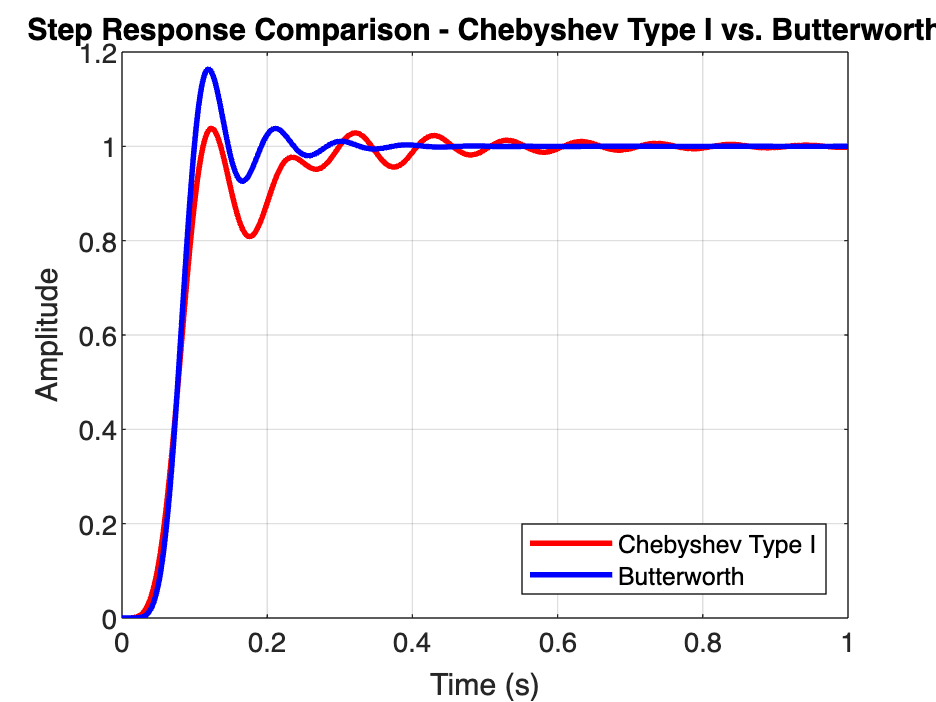


figure;
plot(t, step_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, step_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'southeast');
grid on;